# Standard Radio - EDGE

## Objectif du TP : 

Le but du TP est d’écrire un programme MATLAB qui permet la simulation de la couche physique du EDGE en émission et voir l'effet de la rotation introduite dans la modulation ainsi que l'effet du filtre gaussien sur la constellation I et Q.

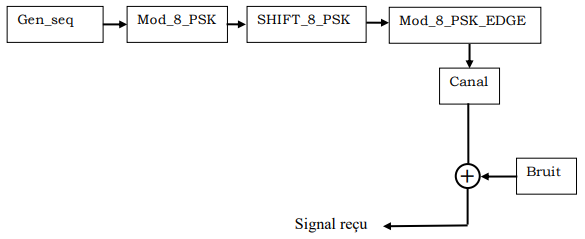

## I) Création du module GEN_SEQ

Le module GEN_SEQ permet de générer une séquence binaire aléatoire de n symboles de 3 bits.

%Définition de la fonction GEN_SEQ qui permet de créer ce module
n=600;
GEN_SEQ=de2bi(randi([0 7], [1 n]), 3, 'left-msb'); % randi([0 7], [1 n]) génère une séquence aléatoire de nombres entiers entre 0 et 7
                                                    % aléatoire de nombres entiers entre 0 et 7 avec n symboles. 
                                                    % de2bi converti chaque nombre en une séquence binaire de 3 bits
                                                    % en plaçant le MSB à gauche
disp(GEN_SEQ); % afficher la séquence binaire générée

     1     0     1
     0     1     0
     0     1     1
     0     0     0
     0     0     0
     1     0     1
     1     0     1
     1     0     0
     0     0     0
     1     0     1
     0     0     0
     0     1     1
     0     1     0
     1     0     1
     0     1     1
     1     1     1
     1     0     1
     0     0     1
     1     0     0
     0     0     0
     1     0     0
     0     1     1
     0     0     1
     1     0     1
     0     1     1
     0     0     0
     0     1     1
     1     1     0
     1     1     1
     1     1     0
     1     0     1
     1     1     1
     1     0     0
     0     0     1
     0     1     1
     1     0     0
     0     0     1
     1     1     0
     1     0     1
     1     1     1
     1     1     0
     0     1     1
     1     0     0
     0     0     1
     1     1     0
     1     1     1
     1     1     0
     0     1     0
     0     1     1
     1     0     0
     0     0     1
     1     1     0
     1     1

## II) Création du module MOD_8_PSK

Le module MOD_8_PSK permet de moduler cette séquence en 8-PSK. Tracer la constellation.

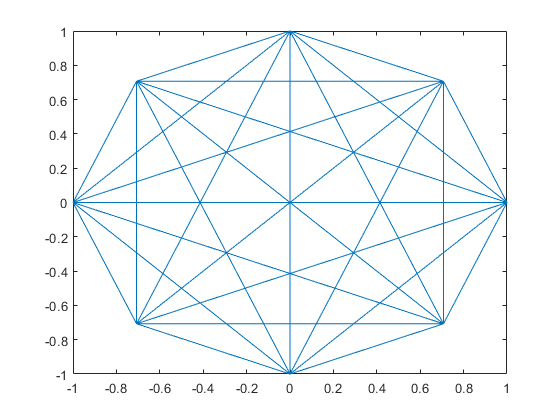

%Définition de la fonction MOD_8_PSK qui permet de créer ce module
MOD_8_PSK=pskmod(bi2de(GEN_SEQ,'left-msb'), 8); % bi2de converti chaque symbole binaire de la séquence générée 
                                                % en un entier entre 0 et 7 en plaçant le MSB à gauche.
                                                % pskmod module la séquence GEN_SEQ en utilisant la modulation 8-PSK
plot(MOD_8_PSK);

## III) Création du module SHIFT_8_PSK

Le module SHIFT_8_PSK permet d'appliquer une rotation de 3.p/8 pour chaque symbole dans la séquence (8-PSK) précédente. Tracez la constellation. Expliquez ce que vous remarquez.

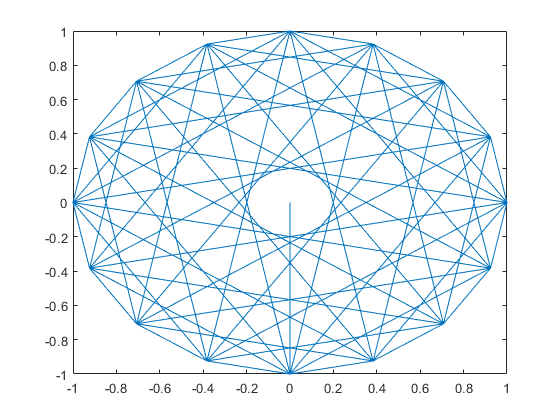

SHIFT_8_PSK=[];
for j=i:length(GEN_SEQ)
    SHIFT_8_PSK(j)=[MOD_8_PSK(j)*exp(1i*3*pi/8*j)];
end

plot(SHIFT_8_PSK);

**Remarque:**

On remarque que le 0 complexe est évité par les droites grâce à la rotation de 3*Pi/8.

## IV) Création du module MOD_8_PSK_EDGE

Le module MOD_8_PSK_EDGE permet de tracer le signal 8-PSK filtré (à l’aide du filtre g donné au cours de la séance). Expliquez ce que vous remarquez.

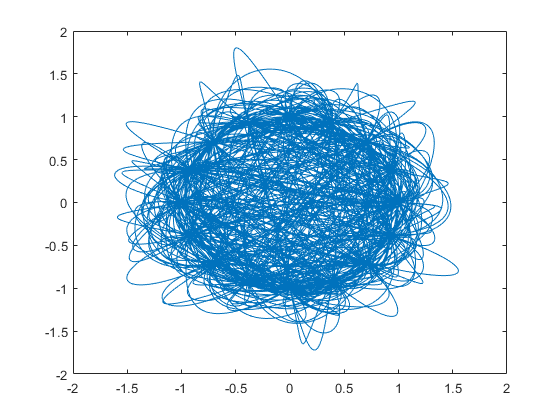

load g

P=37;
Q=1;
RE_ECH2=resample(SHIFT_8_PSK,P,Q);
MOD_8_PSK_EDGE=conv(RE_ECH2,g);

plot(RE_ECH2);

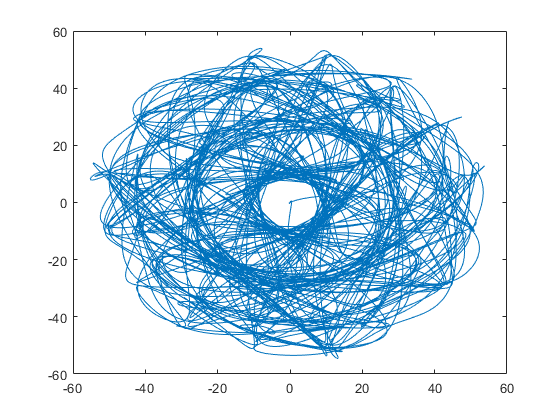

plot(MOD_8_PSK_EDGE);

## Création du bruit

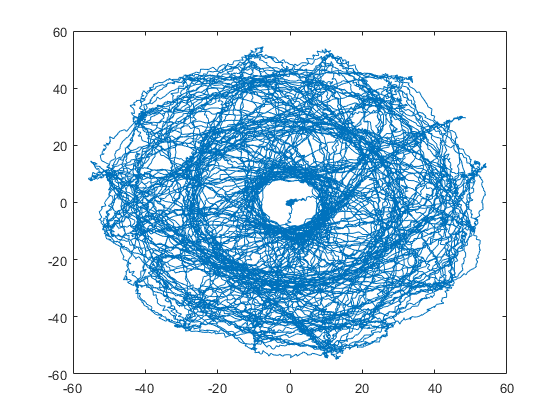

SNR2=5;
NOISE2=awgn(MOD_8_PSK_EDGE,SNR2);

plot(NOISE2);

## Création du canal

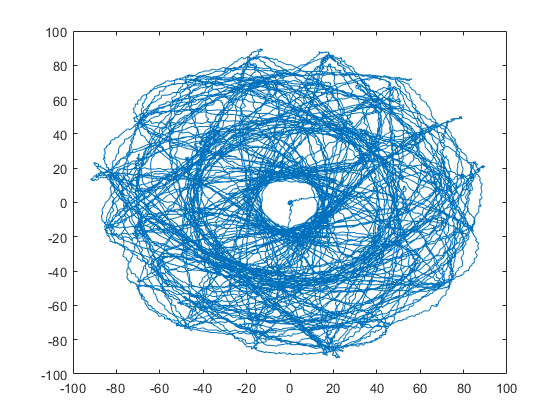

co_canal2=[0 -4 -8 -12 -16 -20];
tv2=size(co_canal2); %Taille du vecteur co_canal
for i=1:tv2(2)
    co_canal2(i)=10^(co_canal2(i)*0.1);
end

CANAL2=awgn(conv(MOD_8_PSK_EDGE,co_canal2),SNR2);

plot(CANAL2);